# Create Deep Learning Network Architecture

Script for creating the layers for a deep learning network with the following properties:

Run the script to create the layers in the workspace variable `lgraph`.

To learn more, see [Generate MATLAB Code From Deep Network Designer](matlab:helpview('deeplearning','generate_matlab_code')).

Auto-generated by MATLAB on 27-May-2024 17:25:02

## Create Layer Graph

Create the layer graph variable to contain the network layers.

lgraph = layerGraph();

## Add Layer Branches

Add the branches of the network to the layer graph. Each branch is a linear array of layers.

tempLayers = [
    imageInputLayer([224 224 3],"Name","imageinput")
    convolution2dLayer([3 3],48,"Name","conv","Padding","same","Stride",[2 2])
    batchNormalizationLayer("Name","batchnorm")
    groupedConvolution2dLayer([3 3],2,"channel-wise","Name","groupedconv","Padding","same","Stride",[2 2])
    geluLayer("Name","gelu")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    groupedConvolution2dLayer([1 1],1,"channel-wise","Name","groupedconv_1","Padding","same")
    batchNormalizationLayer("Name","batchnorm_1")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    groupedConvolution2dLayer([1 1],1,"channel-wise","Name","groupedconv_2","Padding","same")
    batchNormalizationLayer("Name","batchnorm_3")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    transposedConv2dLayer([1 1],96,"Name","transposed-conv","Cropping","same")
    batchNormalizationLayer("Name","batchnorm_2")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    multiplicationLayer(2,"Name","multiplication")
    softmaxLayer("Name","softmax")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = multiplicationLayer(2,"Name","multiplication_1");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    depthConcatenationLayer(4,"Name","depthcat")
    groupedConvolution2dLayer([1 1],1,"channel-wise","Name","groupedconv_3","Padding","same")
    geluLayer("Name","gelu_1")
    convolution2dLayer([1 1],96,"Name","conv_1","Padding","same")
    batchNormalizationLayer("Name","batchnorm_4")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    additionLayer(2,"Name","addition")
    geluLayer("Name","gelu_2")
    groupedConvolution2dLayer([3 3],2,"channel-wise","Name","groupedconv_4","Padding","same","Stride",[2 2])
    batchNormalizationLayer("Name","batchnorm_5")
    geluLayer("Name","gelu_3")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    groupedConvolution2dLayer([1 1],1,"channel-wise","Name","groupedconv_5","Padding","same")
    batchNormalizationLayer("Name","batchnorm_6")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    groupedConvolution2dLayer([1 1],1,"channel-wise","Name","groupedconv_6","Padding","same")
    batchNormalizationLayer("Name","batchnorm_8")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    transposedConv2dLayer([1 1],192,"Name","transposed-conv_1","Cropping","same")
    batchNormalizationLayer("Name","batchnorm_7")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    multiplicationLayer(2,"Name","multiplication_2")
    softmaxLayer("Name","softmax_1")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = multiplicationLayer(2,"Name","multiplication_3");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    depthConcatenationLayer(4,"Name","depthcat_1")
    groupedConvolution2dLayer([1 1],1,"channel-wise","Name","groupedconv_7","Padding","same")
    geluLayer("Name","gelu_4")
    convolution2dLayer([1 1],192,"Name","conv_2","Padding","same")
    batchNormalizationLayer("Name","batchnorm_9")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    additionLayer(2,"Name","addition_1")
    geluLayer("Name","gelu_5")
    groupedConvolution2dLayer([3 3],2,"channel-wise","Name","groupedconv_8","Padding","same","Stride",[2 2])
    batchNormalizationLayer("Name","batchnorm_10")
    geluLayer("Name","gelu_6")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    groupedConvolution2dLayer([1 1],1,"channel-wise","Name","groupedconv_9","Padding","same")
    batchNormalizationLayer("Name","batchnorm_11")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    groupedConvolution2dLayer([1 1],1,"channel-wise","Name","groupedconv_10","Padding","same")
    batchNormalizationLayer("Name","batchnorm_13")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    transposedConv2dLayer([1 1],384,"Name","transposed-conv_2","Cropping","same")
    batchNormalizationLayer("Name","batchnorm_12")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    multiplicationLayer(2,"Name","multiplication_4")
    softmaxLayer("Name","softmax_2")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = multiplicationLayer(2,"Name","multiplication_5");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    depthConcatenationLayer(4,"Name","depthcat_2")
    groupedConvolution2dLayer([1 1],1,"channel-wise","Name","groupedconv_11","Padding","same")
    geluLayer("Name","gelu_7")
    convolution2dLayer([1 1],384,"Name","conv_3","Padding","same")
    batchNormalizationLayer("Name","batchnorm_14")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    additionLayer(2,"Name","addition_2")
    geluLayer("Name","gelu_8")
    groupedConvolution2dLayer([3 3],2,"channel-wise","Name","groupedconv_12","Padding","same","Stride",[2 2])
    batchNormalizationLayer("Name","batchnorm_15")
    geluLayer("Name","gelu_9")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    groupedConvolution2dLayer([1 1],1,"channel-wise","Name","groupedconv_13","Padding","same")
    batchNormalizationLayer("Name","batchnorm_16")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    groupedConvolution2dLayer([1 1],1,"channel-wise","Name","groupedconv_14","Padding","same")
    batchNormalizationLayer("Name","batchnorm_18")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    transposedConv2dLayer([1 1],768,"Name","transposed-conv_3","Cropping","same")
    batchNormalizationLayer("Name","batchnorm_17")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    multiplicationLayer(2,"Name","multiplication_6")
    softmaxLayer("Name","softmax_3")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = multiplicationLayer(2,"Name","multiplication_7");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    depthConcatenationLayer(4,"Name","depthcat_3")
    groupedConvolution2dLayer([1 1],1,"channel-wise","Name","groupedconv_15","Padding","same")
    geluLayer("Name","gelu_10")
    convolution2dLayer([1 1],768,"Name","conv_4","Padding","same")
    batchNormalizationLayer("Name","batchnorm_19")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    additionLayer(2,"Name","addition_3")
    geluLayer("Name","gelu_11")
    globalAveragePooling2dLayer("Name","gapool")
    flattenLayer("Name","flatten")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    selfAttentionLayer(3,192,"Name","selfattention")
    batchNormalizationLayer("Name","batchnorm_20")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = additionLayer(2,"Name","addition_4");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    batchNormalizationLayer("Name","batchnorm_21")
    bilstmLayer(384,"Name","bilstm")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    additionLayer(2,"Name","addition_5")
    fullyConnectedLayer(2,"Name","fc")
    softmaxLayer("Name","softmax_4")
    classificationLayer("Name","classoutput")];
lgraph = addLayers(lgraph,tempLayers);

% clean up helper variable
clear tempLayers;

## Connect Layer Branches

Connect all the branches of the network to create the network graph.

lgraph = connectLayers(lgraph,"gelu","groupedconv_1");
lgraph = connectLayers(lgraph,"gelu","groupedconv_2");
lgraph = connectLayers(lgraph,"gelu","transposed-conv");
lgraph = connectLayers(lgraph,"gelu","addition/in1");
lgraph = connectLayers(lgraph,"batchnorm_1","multiplication/in1");
lgraph = connectLayers(lgraph,"batchnorm_1","depthcat/in2");
lgraph = connectLayers(lgraph,"batchnorm_3","multiplication_1/in1");
lgraph = connectLayers(lgraph,"batchnorm_3","depthcat/in1");
lgraph = connectLayers(lgraph,"batchnorm_2","multiplication/in2");
lgraph = connectLayers(lgraph,"batchnorm_2","depthcat/in3");
lgraph = connectLayers(lgraph,"softmax","multiplication_1/in2");
lgraph = connectLayers(lgraph,"multiplication_1","depthcat/in4");
lgraph = connectLayers(lgraph,"batchnorm_4","addition/in2");
lgraph = connectLayers(lgraph,"gelu_3","groupedconv_5");
lgraph = connectLayers(lgraph,"gelu_3","groupedconv_6");
lgraph = connectLayers(lgraph,"gelu_3","transposed-conv_1");
lgraph = connectLayers(lgraph,"gelu_3","addition_1/in1");
lgraph = connectLayers(lgraph,"batchnorm_6","multiplication_2/in1");
lgraph = connectLayers(lgraph,"batchnorm_6","depthcat_1/in2");
lgraph = connectLayers(lgraph,"batchnorm_8","multiplication_3/in1");
lgraph = connectLayers(lgraph,"batchnorm_8","depthcat_1/in1");
lgraph = connectLayers(lgraph,"batchnorm_7","multiplication_2/in2");
lgraph = connectLayers(lgraph,"batchnorm_7","depthcat_1/in3");
lgraph = connectLayers(lgraph,"softmax_1","multiplication_3/in2");
lgraph = connectLayers(lgraph,"multiplication_3","depthcat_1/in4");
lgraph = connectLayers(lgraph,"batchnorm_9","addition_1/in2");
lgraph = connectLayers(lgraph,"gelu_6","groupedconv_9");
lgraph = connectLayers(lgraph,"gelu_6","groupedconv_10");
lgraph = connectLayers(lgraph,"gelu_6","transposed-conv_2");
lgraph = connectLayers(lgraph,"gelu_6","addition_2/in1");
lgraph = connectLayers(lgraph,"batchnorm_11","multiplication_4/in1");
lgraph = connectLayers(lgraph,"batchnorm_11","depthcat_2/in2");
lgraph = connectLayers(lgraph,"batchnorm_13","multiplication_5/in1");
lgraph = connectLayers(lgraph,"batchnorm_13","depthcat_2/in1");
lgraph = connectLayers(lgraph,"batchnorm_12","multiplication_4/in2");
lgraph = connectLayers(lgraph,"batchnorm_12","depthcat_2/in3");
lgraph = connectLayers(lgraph,"softmax_2","multiplication_5/in2");
lgraph = connectLayers(lgraph,"multiplication_5","depthcat_2/in4");
lgraph = connectLayers(lgraph,"batchnorm_14","addition_2/in2");
lgraph = connectLayers(lgraph,"gelu_9","groupedconv_13");
lgraph = connectLayers(lgraph,"gelu_9","groupedconv_14");
lgraph = connectLayers(lgraph,"gelu_9","transposed-conv_3");
lgraph = connectLayers(lgraph,"gelu_9","addition_3/in1");
lgraph = connectLayers(lgraph,"batchnorm_16","multiplication_6/in1");
lgraph = connectLayers(lgraph,"batchnorm_16","depthcat_3/in2");
lgraph = connectLayers(lgraph,"batchnorm_18","multiplication_7/in1");
lgraph = connectLayers(lgraph,"batchnorm_18","depthcat_3/in1");
lgraph = connectLayers(lgraph,"batchnorm_17","multiplication_6/in2");
lgraph = connectLayers(lgraph,"batchnorm_17","depthcat_3/in3");
lgraph = connectLayers(lgraph,"softmax_3","multiplication_7/in2");
lgraph = connectLayers(lgraph,"multiplication_7","depthcat_3/in4");
lgraph = connectLayers(lgraph,"batchnorm_19","addition_3/in2");
lgraph = connectLayers(lgraph,"flatten","selfattention");
lgraph = connectLayers(lgraph,"flatten","addition_4/in1");
lgraph = connectLayers(lgraph,"batchnorm_20","addition_4/in2");
lgraph = connectLayers(lgraph,"addition_4","batchnorm_21");
lgraph = connectLayers(lgraph,"addition_4","addition_5/in2");
lgraph = connectLayers(lgraph,"bilstm","addition_5/in1");

## Plot Layers

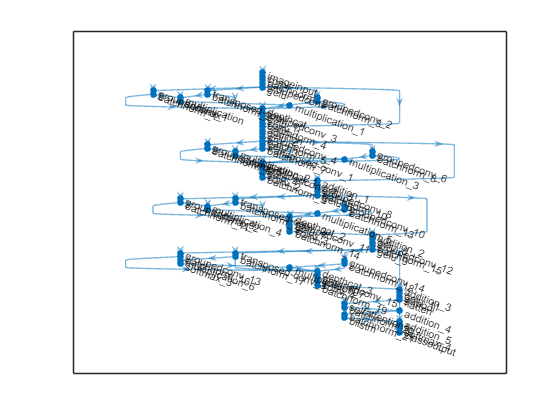

plot(lgraph);